# Validazione

clear; close all; clc;

simulation.author = 'M';
Nprova = 42;

Aggiungo opzione per evitare la molteplicità di 360° nella base

bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';

## Definizione del sistema controllato

model_initialization;

Accelerazione massima e Rest Time.

cs.setMaxAcceleration(15);
cs.setRestTime(0.1);

## Definizione segnale eccitante

Utilizzo di segnali multisinusoidali per introdurre variabilità rispetto ai dati di training.

La metrica usata per valutare la bontà del fit è la seguente, implementata nella function `compute_fit_goodness`:

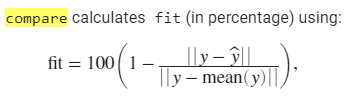

### Parametri

Calcoliamo la massima pulsazione ammissibile per il segnale. Deve essere al massimo la metà della pulsazione di campionamento al fine di evitare fenomeni di aliasing (Teorema di Shannon).

Estraiamo inoltre dal sistema la massima coppia che ciascun motore può erogare.

w_max = pi/st %rad/s     Fs=1/Ts, Ws=2*pi/Ts, 0.5*Ws=pi/Ts

w_max = 3.1416e+03

umax = system.getUMax

umax =    150
   150


% Sinusoidi
w0_sin = 0.5; w1_sin = w_max;       % wide, main sine pack
w0b_sin = 20; w1b_sin = 1000;     % narrow, secondary sine pack
ampiezza_sin = 120;
num_sin = 30;
numb_sin = 30;

% Portante
w_portante=w0_sin/20;
ampiezza_portante=20;
T_portante=2*pi/w_portante;

### Portante

durata_simulazione = 1.1*T_portante; % secondi
t = (0:st:durata_simulazione)';
portante = ampiezza_portante*sin(w_portante*t);

durata_teorica = seconds(durata_simulazione); % debug
durata_teorica.Format = 'hh:mm:ss';
display(durata_teorica)

durata_teorica = duration
   00:00:13


n_samples = length(t) % debug

n_samples = 13824

sample_computation_time = 0.01; % stimato empiricamente su 100 run di cs.openloop (risulta circa 0.01, 10 volte il tempo di campionamento)
                                % => quindi la durata reale (quanto ci impiega il codice) sarà 10 volte la durata teorica calcolata sopra
durata_reale = n_samples*sample_computation_time; % debug
durata_reale = seconds(durata_reale); % debug
durata_reale.Format = 'hh:mm:ss';
display(durata_reale)

durata_reale = duration
   00:02:18


### Multisinusoidi

Scelgo le sinusoidi come un vettore composto da due pacchi di sinusoidi

omega=sort([logspace(log10(w0_sin),log10(w1_sin),num_sin)' ; ...
            logspace(log10(w0b_sin),log10(w1b_sin),numb_sin)']); % In questo modo è possibile concentrare le sinusoidi in punti specifici

arrotondo a dei multipli della portante e rimuovo eventuali duplicati

omega=round(omega/w_portante)*w_portante; % arrotondo per avere le omega multiple della portante
omega=unique(omega);

Creo il segnale come somma di sinusoidi sfasate e con ampiezza diversa (massima variabilità possibile per il test)

multisine_signal=zeros(length(t),1);
for idx=1:length(omega)
    fase=rand*2*pi;
    ampiezza_relativa=0.5*ampiezza_sin*(1+rand); % ampiezze random tra ampiezza_sin/2 e ampiezza_sin
    coeff_sin=sin(fase)*ampiezza_relativa; coeff_cos=cos(fase)*ampiezza_relativa;
    multisine_signal=multisine_signal+coeff_cos*sin(omega(idx)*t)+coeff_sin*cos(omega(idx)*t); % sin(alpha+beta) = sin(alpha)cos(beta)+cos(alpha)sin(beta)
end


% imposizione della massima ampiezza
multisine_signal=multisine_signal/max(multisine_signal)*ampiezza_sin;

### Somma dei segnali

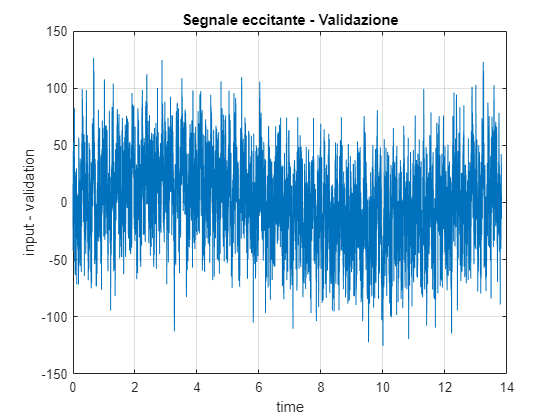

input_signal = portante+multisine_signal;

fig_inputSignal = figure;
plot(t,input_signal);
xlabel('time'); ylabel('input - validation'); title('Segnale eccitante - Validazione'); grid on;

### Selezione dei sottosistemi di cui eseguire la validazione

joint1 = true;
joint2 = true;

if joint1 && ~ joint2
    control_action = [input_signal zeros(length(input_signal),1)];
elseif joint2 && ~ joint1
    control_action = [zeros(length(input_signal),1) input_signal];
elseif joint1 && joint2
    control_action = [input_signal input_signal];
else
    error('Selezionare almeno 1 giunto!')
end

## Simulazione sistema

checkSimulation = true;     checkLoadingData = false;

if checkSimulation

    f = waitbar(0,'0','Name','Simulazione - Validazione',...
                'CreateCancelBtn','setappdata(gcbf,''canceling'',1)');
    setappdata(f,'canceling',0);

    execution_time = zeros(length(t),1); % debug

    for idx=1:length(t)
        tic
        
        % Check for clicked Cancel button
        if getappdata(f,'canceling')
            break
        end
        
        [process_output(idx,:),tt(idx,1)]=cs.openloop(control_action(idx,:));

        % Update waitbar and message
        percent_progress = idx/length(t)*100;
        waitbar(percent_progress/100,f,sprintf('%.2f %%',percent_progress))

        execution_time(idx) = toc; % debug
    end

    beep

    delete(f)

    disp('Tempo di esecuzione medio di una singola simulazione')
    mean_execution_time = mean(execution_time) % debug

else % checkLoadingData
    load(directorySimulation);    
end

Tempo di esecuzione medio di una singola simulazione


mean_execution_time = 0.0224

## Calcolo della risposta in frequenza

Aggiungo opzione per evitare la molteplicità di 360° nella base

bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';

Caricare il modello (fatto qui in modo da avere anche la f.d.t. dell'identificazione per plottarli insieme alla f.d.t della validazione)

simulation.author = 'M';
Nprova_ident = 42;

modelName = strcat(simulation.author,'_model_', num2str(Nprova_ident));
directoryModel = strcat('.\estimated_models\data\',modelName);
load(directoryModel);

### F.d.t. coppia-velocità giunto 1

Calcolo la risposta in frequenza e la plotto. Plotto anche la frequenza di inizio del segnale eccitante

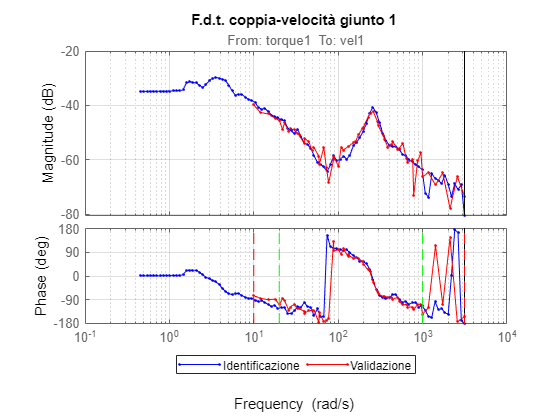

if (joint1)    
    % calcolo coefficienti di Fourier di ingresso e uscita
    control_action_coeff_joint1 = fourierCoefficients(tt,control_action(1:length(tt),1),w_portante,omega);
    process_output_coeff_joint1 = fourierCoefficients(tt,process_output(:,3),w_portante,omega);
    
    % Y(j*omega)/U(j*omega) -> RISPOSTA IN FREQUENZA SPERIMENTALE
    freq_resp_valid_joint1 = idfrd(process_output_coeff_joint1./control_action_coeff_joint1,omega,st);
    freq_resp_valid_joint1.OutputName = 'vel1'; freq_resp_valid_joint1.InputName = 'torque1';
    frequency = freq_resp_valid_joint1.Frequency;

    fig_j1 = figure;
    bode(freq_resp_ident_joint1,'.-b',bode_opts)
    grid on
    hold on
    bode(freq_resp_valid_joint1,'.-r',bode_opts)
    plot(w0_sin*[1 1],ylim,'--r'); plot(w1_sin*[1 1],ylim,'--r')
    plot(w0b_sin*[1 1],ylim,'--g'); plot(w1b_sin*[1 1],ylim,'--g')
    hold off
    title('F.d.t. coppia-velocità giunto 1')
    legend('Identificazione','Validazione','Location','southoutside','Orientation','horizontal')
end

### F.d.t. coppia-velocità giunto 2

Calcolo la risposta in frequenza con il comando e la plotto. Plotto anche la frequenza di inizio del segnale eccitante

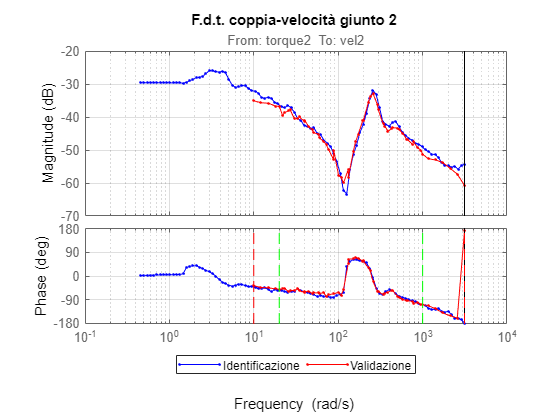

if (joint2)
    % calcolo coefficienti di Fourier di ingresso e uscita
    control_action_coeff_joint2 = fourierCoefficients(tt,control_action(1:length(tt),1),w_portante,omega);
    process_output_coeff_joint2 = fourierCoefficients(tt,process_output(:,4),w_portante,omega);
    
    % Y(j*omega)/U(j*omega) -> RISPOSTA IN FREQUENZA SPERIMENTALE
    freq_resp_valid_joint2 = idfrd(process_output_coeff_joint2./control_action_coeff_joint2,omega,st);
    freq_resp_valid_joint2.OutputName = 'vel2'; freq_resp_valid_joint2.InputName = 'torque2';
    frequency = freq_resp_valid_joint2.Frequency;

    fig_j2 = figure;
    bode(freq_resp_ident_joint2,'.-b',bode_opts)
    grid on
    hold on
    bode(freq_resp_valid_joint2,'.-r',bode_opts)
    plot(w0_sin*[1 1],ylim,'--r'); plot(w1_sin*[1 1],ylim,'--r')
    plot(w0b_sin*[1 1],ylim,'--g'); plot(w1b_sin*[1 1],ylim,'--g')
    hold off
    title('F.d.t. coppia-velocità giunto 2')
    legend('Identificazione','Validazione','Location','southoutside','Orientation','horizontal')
end

## Grafico dei risultati

system.getInputName

ans = 1×2 cell array
    {'torque_1'}    {'torque_2'}


system.getOutputName

ans = 1×4 cell array
    {'position_1'}    {'position_2'}    {'velocity_1'}    {'velocity_2'}


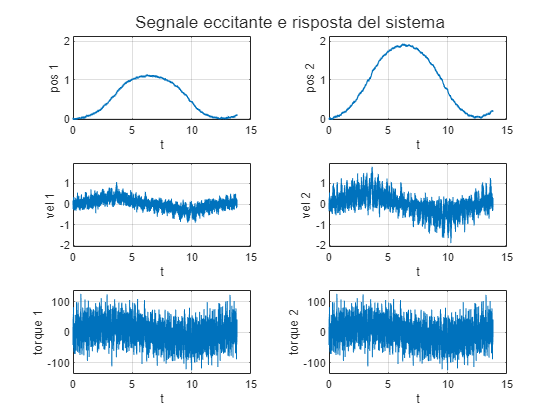

pos1=process_output(:,1); pos2=process_output(:,2);
vel1=process_output(:,3); vel2=process_output(:,4);
tau1=control_action(:,1); tau2=control_action(:,2);

% coppia considerando la saturazione e solo i samples effettivamente
% calcolati durante la simulazione (anche se questa è stata interrotta a un
% certo punto)
actual_tau1 = min(max(tau1(1:length(tt)),-umax(1)),umax(1));
actual_tau2 = min(max(tau2(1:length(tt)),-umax(2)),umax(2));


fig_res = figure;
tl = tiledlayout(3,2);

nexttile; plot(tt,pos1); grid on; xlabel('t'); ylabel('pos 1'); ylim([1.1*min([pos1;pos2]) 1.1*max([pos1;pos2])])
nexttile; plot(tt,pos2); grid on; xlabel('t'); ylabel('pos 2'); ylim([1.1*min([pos1;pos2]) 1.1*max([pos1;pos2])])

nexttile; plot(tt,vel1); grid on; xlabel('t'); ylabel('vel 1'); ylim([1.1*min([vel1;vel2]) 1.1*max([vel1;vel2])])
nexttile; plot(tt,vel2); grid on; xlabel('t'); ylabel('vel 2'); ylim([1.1*min([vel1;vel2]) 1.1*max([vel1;vel2])])

nexttile; plot(tt,actual_tau1); grid on; xlabel('t'); ylabel('torque 1');
ylim([1.1*min([actual_tau1;actual_tau2]) 1.1*max([actual_tau1;actual_tau2])])

nexttile; plot(tt,actual_tau2); grid on; xlabel('t'); ylabel('torque 2');
ylim([1.1*min([actual_tau1;actual_tau2]) 1.1*max([actual_tau1;actual_tau2])])

title(tl,'Segnale eccitante e risposta del sistema')

## Salvataggio simulazione

if checkSimulation
    % Selezionare il file
    simulationName = strcat(simulation.author,'_simulation_',num2str(Nprova));
    directorySimulation = strcat('.\simulations\validation\data\',simulationName);
    directoryFig = strcat('.\simulations\validation\figures\',simulationName);

    % Salvataggio della simulazione
    simulation.description = 'chirp + portante - j1';
    simulation.w0_sin = w0_sin;
    simulation.w1_sin = w1_sin;
    simulation.wportante = w_portante;
    simulation.ampiezza_sin = ampiezza_sin;
    simulation.ampiezza_portante = ampiezza_portante;
    simulation.durata_simulazione = durata_simulazione;
    simulation.control_action = control_action;
    simulation.process_output = process_output;
    simulation.tt = tt;
    simulation.joint1 = joint1;
    simulation.joint2 = joint2;
    simulation.durata_teorica = durata_teorica;
    simulation.durata_reale = durata_reale;

    save(directorySimulation,'-struct','simulation')

    if (joint1)
        savefig(fig_j1,strcat(directoryFig,'_j1'))
    end
    if (joint2)
        savefig(fig_j2,strcat(directoryFig,'_j2'))
    end
    savefig(fig_res,strcat(directoryFig,'_res'))
    savefig(fig_inputSignal,strcat(directoryFig,'_inputSignal'))
end

## Valutazione del modello

### F.d.t. coppia-velocità giunto 1

Plotto i dati sperimentali con l'intervallo di confidenza (in questo caso 3*sigma)

if (joint1)
    fig_j1 = figure;
    h = bodeplot(freq_resp_valid_joint1,bode_opts);
    hold on
    showConfidence(h,3)

           Grafico i modelli stimati

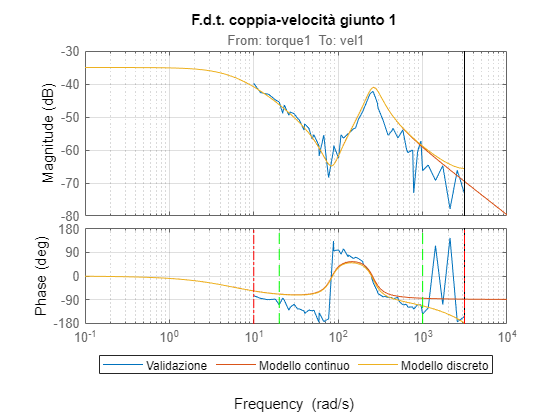

Bontà percentuale del fitting tra w0 e w1:


fitC_joint1 = 48.4494

fitD_joint1 = 48.3372

    bode(modelC_joint1,modelD_joint1,bode_opts)
    
    % range frequenze investigate
    plot(w0_sin*[1 1],ylim,'-.r'); plot(w1_sin*[1 1],ylim,'-.r')
    plot(w0b_sin*[1 1],ylim,'--g'); plot(w1b_sin*[1 1],ylim,'--g')
    
    grid on
    hold off
    legend('Validazione','Modello continuo','Modello discreto','Location','southoutside','Orientation','horizontal')
    title('F.d.t. coppia-velocità giunto 1')

    % quantificazione bontà del fitting
    val_points_joint1 = reshape(abs(freq_resp_valid_joint1.ResponseData),1,[]);
    modelC_points_joint1 = reshape(abs(freqresp(modelC_joint1,freq_resp_valid_joint1.Frequency)),1,[]);
    modelD_points_joint1 = reshape(abs(freqresp(modelD_joint1,freq_resp_valid_joint1.Frequency)),1,[]);

    disp('Bontà percentuale del fitting tra w0 e w1:')
    fitC_joint1 = compute_fit_goodness(val_points_joint1,modelC_points_joint1,frequency,w0_sin,w1_sin)
    fitD_joint1 = compute_fit_goodness(val_points_joint1,modelD_points_joint1,frequency,w0_sin,w1_sin)
end

### F.d.t. coppia-velocità giunto 2

Plotto i dati sperimentali con l'intervallo di confidenza (in questo caso 3*sigma)

if (joint2)
    fig_j2 = figure;
    h = bodeplot(freq_resp_valid_joint2,bode_opts);
    hold on
    showConfidence(h,3)

           Grafico i modelli stimati

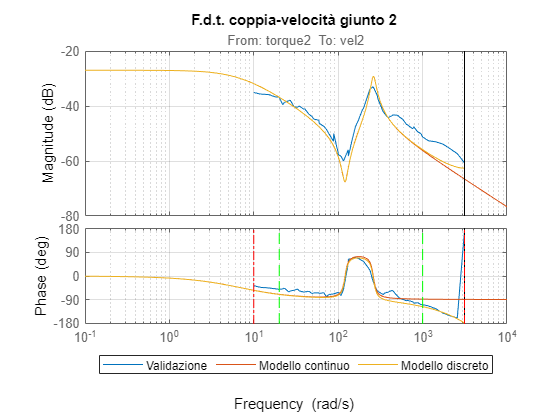

Bontà percentuale del fitting tra w0 e w1:


fitC_joint2 = 52.4802

fitD_joint2 = 52.8053

    bode(modelC_joint2,modelD_joint2,bode_opts)
    
    % range frequenze investigate
    plot(w0_sin*[1 1],ylim,'-.r'); plot(w1_sin*[1 1],ylim,'-.r')
    plot(w0b_sin*[1 1],ylim,'--g'); plot(w1b_sin*[1 1],ylim,'--g')
    
    grid on
    hold off
    legend('Validazione','Modello continuo','Modello discreto','Location','southoutside','Orientation','horizontal')
    title('F.d.t. coppia-velocità giunto 2')

    % quantificazione bontà del fitting
    val_points_joint2 = reshape(abs(freq_resp_valid_joint2.ResponseData),1,[]);
    modelC_points_joint2 = reshape(abs(freqresp(modelC_joint2,freq_resp_valid_joint2.Frequency)),1,[]);
    modelD_points_joint2 = reshape(abs(freqresp(modelD_joint2,freq_resp_valid_joint2.Frequency)),1,[]);

    disp('Bontà percentuale del fitting tra w0 e w1:')
    fitC_joint2 = compute_fit_goodness(val_points_joint2,modelC_points_joint2,frequency,w0_sin,w1_sin)
    fitD_joint2 = compute_fit_goodness(val_points_joint2,modelD_points_joint2,frequency,w0_sin,w1_sin)
end

## Salvataggio plot modelli validati

% Selezionare il file
modelName = strcat(simulation.author,'_model_', num2str(Nprova));
directoryModel = strcat('.\validated_models\data\',modelName);
directoryFig = strcat('.\validated_models\figures\',modelName);

validatedModel.simulation = simulation;
validatedModel.joint1 = joint1;                 validatedModel.joint2 = joint2;
validatedModel.fitC_joint1 = [];                validatedModel.fitD_joint1 = [];
validatedModel.fitC_joint2 = [];                validatedModel.fitD_joint2 = [];

if (joint1)
    validatedModel.fitC_joint1 = fitC_joint1;        validatedModel.fitD_joint1 = fitD_joint1;
    
    savefig(fig_j1,strcat(directoryFig,'_j1'))
end

if (joint2)
    validatedModel.fitC_joint2 = fitC_joint2;        validatedModel.fitD_joint2 = fitD_joint2;
    
    savefig(fig_j2,strcat(directoryFig,'_j2'))
end

save(directoryModel,'-struct','validatedModel')    

## Comando `compare`

Sezione per testare il comando e vedere se il calcolo del fit in un certo range frequenziale coincide con quello eseguito dalla funzione `compute_fit_goodness => `***Risultati compatibili, anche se il calcolo fatto manualmente sembra più accurato***

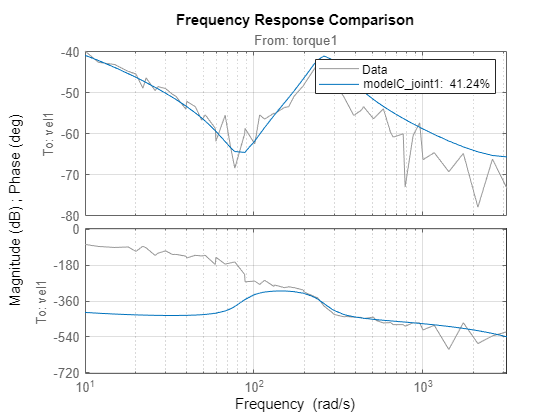

compare(freq_resp_valid_joint1,modelC_joint1)

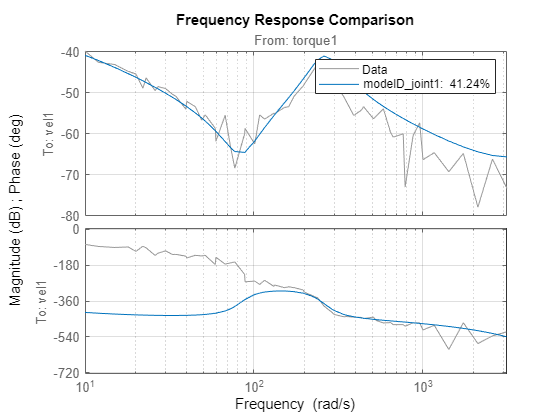

compare(freq_resp_valid_joint1,modelD_joint1)

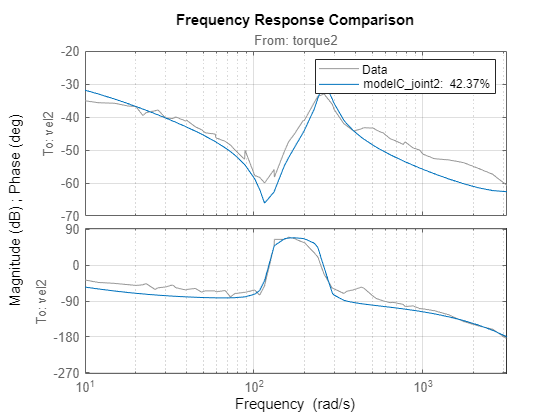

compare(freq_resp_valid_joint2,modelC_joint2)

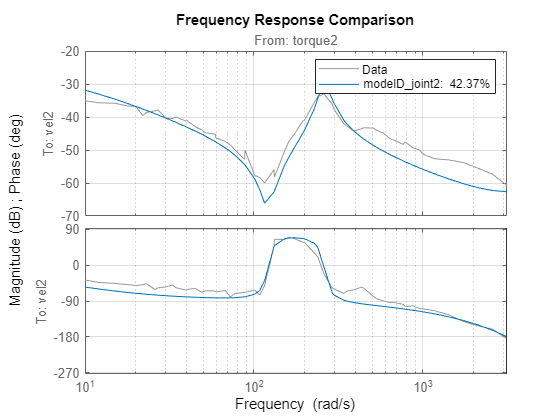

compare(freq_resp_valid_joint2,modelD_joint2)